img_path='Samples\0001';
addpath(img_path);
addpath('Functions\DetectROI');
addpath('Functions\Gabor');
ROIL=repmat(struct('image',uint8(zeros(192,192))),1,5);
OB=repmat(struct('image',uint8(zeros(192,192))),1,5);
GABORL=repmat(struct('image',uint8(zeros(192,192))),1,5);
for i=1:5
    ROIL(i).image=findROI(img_path, ['\0001_m_l_0' num2str(i) '.jpg'],192,150);
    ROIL(i).image = uint8(255*mat2gray(ROIL(i).image));
    ROIL(i).image = medfilt2(ROIL(i).image,[9 9]);
end

## cari ROI

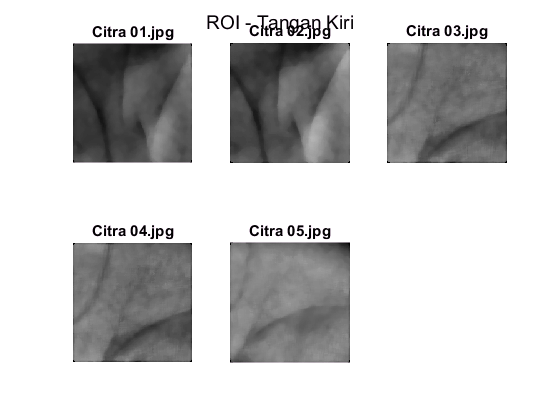

figure;
suptitle('ROI - Tangan Kiri');
for j=1:5
    subplot(2,3,j)
    imshow(ROIL(j).image);
    title(['Citra 0' num2str(j) '.jpg']);
end

## Deteksi Tepi

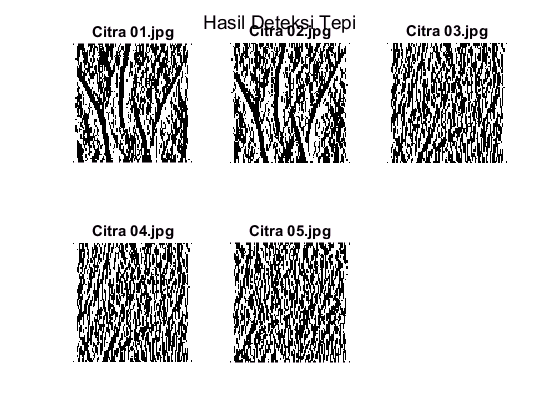

figure;
suptitle('Hasil Deteksi Tepi');
h = [ -1  2  -1 
      -1  2  -1
     -1 2 -1 ];
for j=1:5
    subplot(2,3,j)
    ROIL(j).image = imresize(ROIL(j).image, [96 96]);
    ROIL(j).image = filter2(h, ROIL(j).image);
    %imL_bf_filter=edge(ROIL(j).image,'sobel');
    %imL_af_filter=bwmorph(imL_bf_filter,'bridge');
    imshow(ROIL(j).image);
    title(['Citra 0' num2str(j) '.jpg']);
end

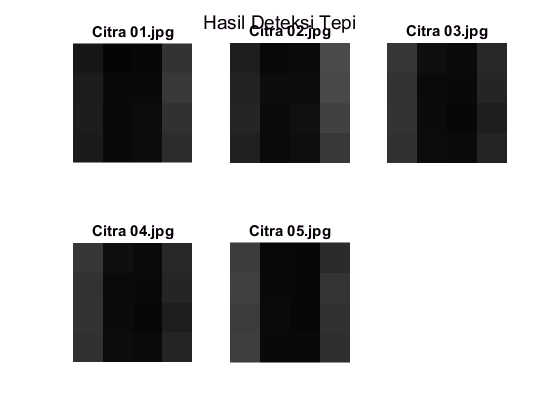

figure;
suptitle('Hasil Deteksi Tepi');
fun = @(block_struct) ...
   std2(block_struct.data) * ones(size(block_struct.data));
for j=1:5
    subplot(2,3,j)
    OB(j).image = blockproc(ROIL(j).image,[24 24],fun);
    OB(j).image = imresize(uint8(OB(j).image), [4 4]);
    imshow(OB(j).image);
    title(['Citra 0' num2str(j) '.jpg']);
end


OB_distnorm = norm(double(OB(2).image)-double(OB(4).image))/sqrt(numel(double(OB(2).image)))

OB_distnorm = 18.3478

OB_dist = norm(double(OB(1).image) - double(OB(2).image))

OB_dist = 38.2208

## Gabor

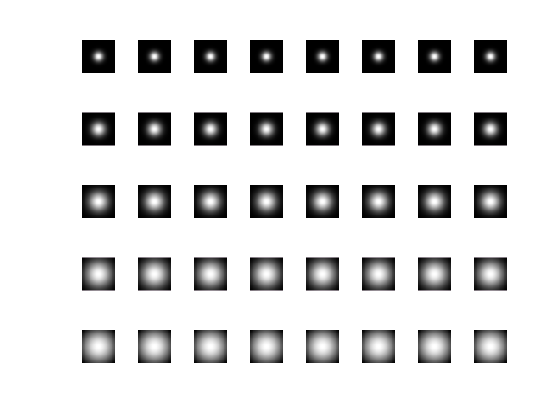

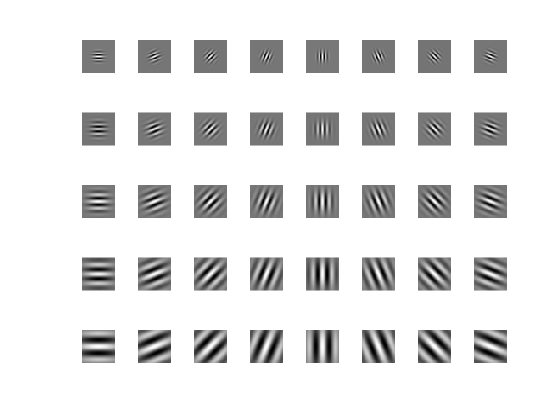


gaborArray = gaborFilterBank(5,8,39,39);  % Generates the Gabor filter bank

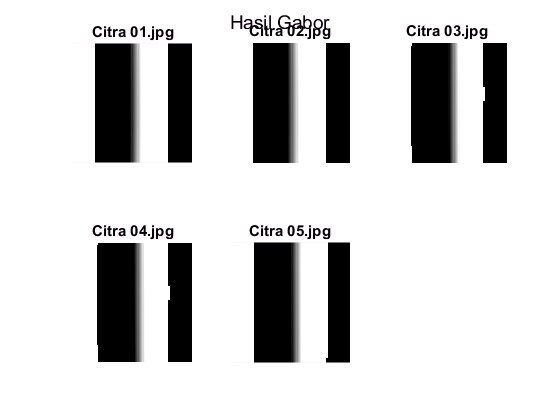

wavelength = 64;
orientation = 0;
figure;
suptitle('Hasil Gabor');
for i=1:5
    featureVector{i} = gaborFeatures(ROIL(i).image,gaborArray,4,4);
    subplot(2,3,i)
    [mag,phase] = imgaborfilt(ROIL(i).image,wavelength,orientation);
    GABORL(i).image = imbinarize(phase);
    imshow(phase);
    title(['Citra 0' num2str(i) '.jpg']);
end

distance = norm(featureVector{2} - featureVector{1});


dif = xor(GABORL(1).image,GABORL(2).image);
skorPerbedaan = nnz(dif) %mencari nilai 1 pada matrik

skorPerbedaan = 0

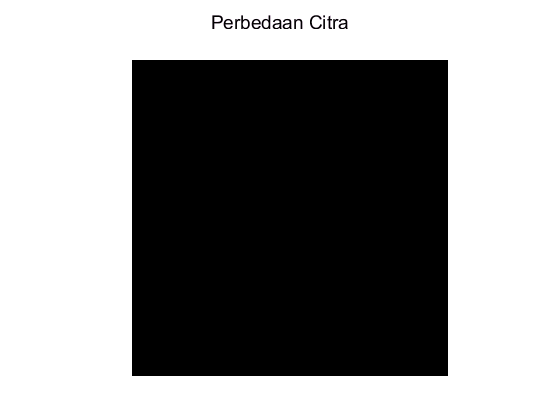

figure;
suptitle('Perbedaan Citra');
imshow(dif);